
%-------------------------- Code Percolation en conduction thermique 2D--------------------------------------

%----------------------- -------------Cas hétérogène ------------------------------------------------------


clear all;
close all;

Lx = 1; %Longueur x
Ly = 1; %Longueur y
r = 0.001; % Rayon des charges
fs = 0.2; % Fraction surfacique de charges
kc = 10; % Conductivité charges
ki = 1; % Conductivité isolant
Nx = 512; % Nb de points x
Ny = 512; %Nb de points y

% [X, f, k, dx, dy, filename] = resolutionThermique(Nx, Ny, r, fs, kc, ki, Lx, Ly);
% 
% %Tracé
% Tet=reshape(X,Ny,Nx);
% Tet = flipud(Tet); 
% contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
% title('Champ de température normalisé')
% xlabel('x (en m)')
% 
% figure;
% Tet=reshape(X,Ny,Nx);
% Tet = flipud(Tet);                              % inverse l'ordre des lignes : la ligne 1 passe en haut du tracé
% Nlev = 300;                        % Nombre de lignes de contour voulu
% Ts = sort(Tet(:));                 % Un seul vecteur colonne, classé de la plus petite à la plus grande
% niveaux = unique(Ts(round(linspace(1,numel(Ts),Nlev))));    % Niveaux équi-répartis en surface
% contour(0:dx:Lx, 0:dy:Ly, Tet, niveaux)                     % Trace les isothermes aux niveaux choisis
% title('Champ de température normalisé')
% xlabel('x (en m)')
% 
% 
% S = LoadMatrix(filename);
% figure;
% imagesc(full(S));
% colormap(hot);
% 
% 
tic
[kl, f, filename]= PercolationGenerator2D(Nx, Ny, Lx, Ly, r, fs, false, false); %Conductivité thermique
toc

Elapsed time is 0.334202 seconds.


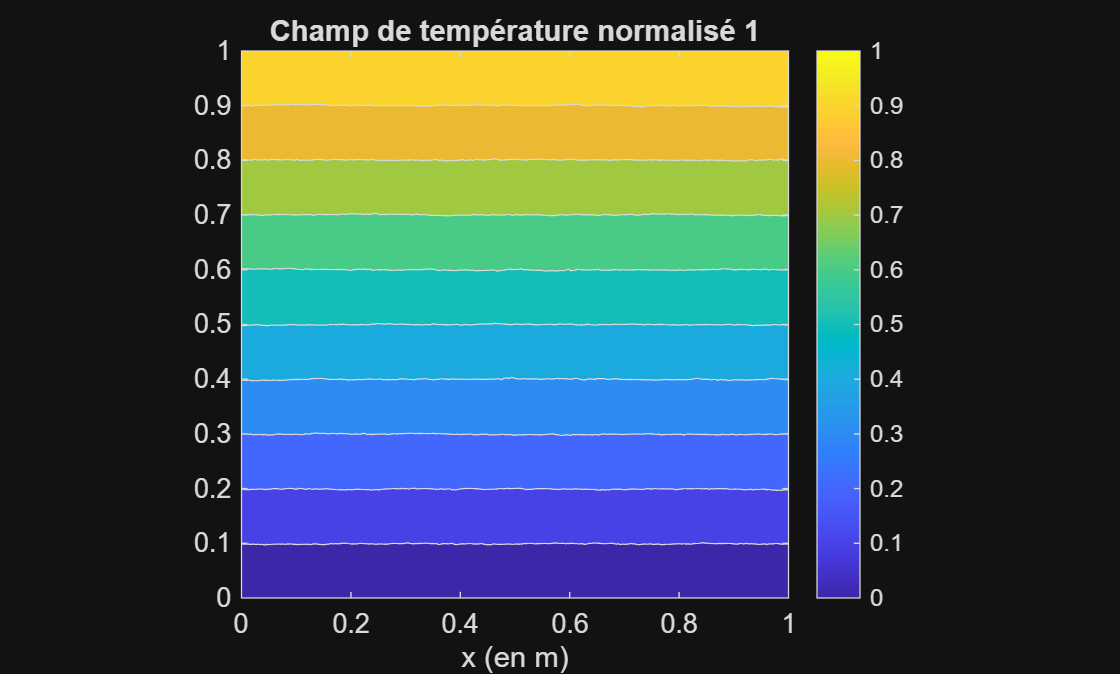

[X, k, dx, dy] = resVolFini2D(Nx, Ny, kl, kc, ki, Lx, Ly);

%Tracé
Tet=reshape(X,Ny,Nx);
Tet = flipud(Tet); 
k = flipud(k); 
contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
title('Champ de température normalisé 1')
xlabel('x (en m)')
colorbar();
axis equal

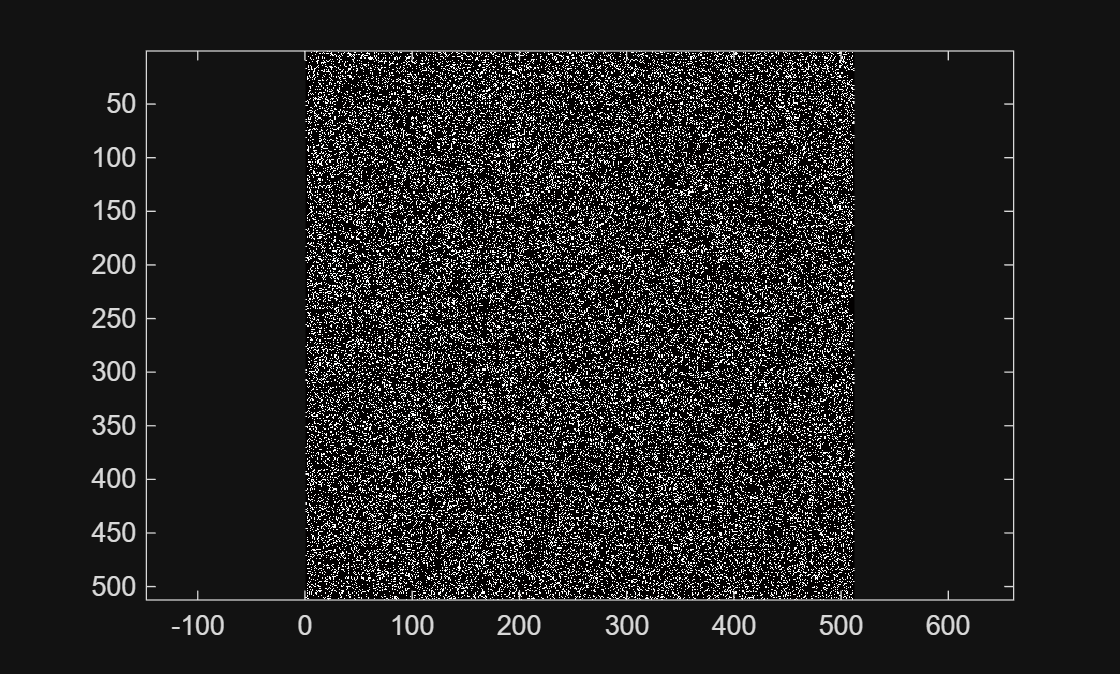


figure;
imagesc(kl);
colormap(hot);
axis equal

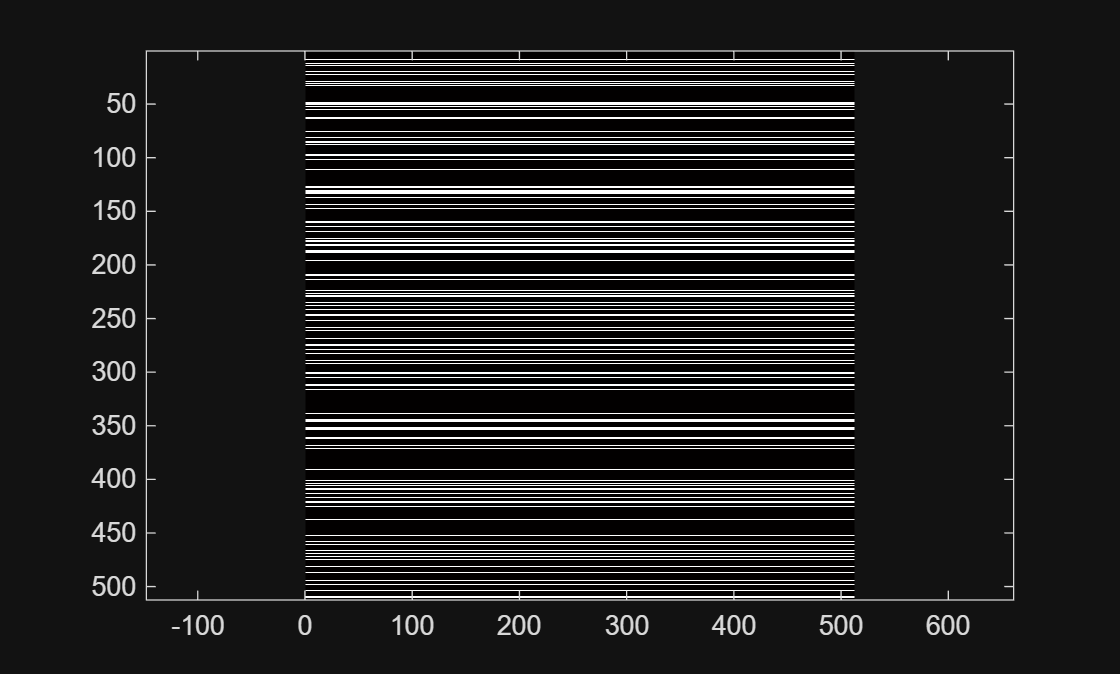


% Génération des charges en lignes (cas le moins conducteur)

[kmin, tempFs, filename] = PercolationGenerator2Dmin(Nx, Ny, Lx, Ly, r, fs, false, false);
[X, k, dx, dy] = resVolFini2D(Nx, Ny, kmin, kc, ki, Lx, Ly);

figure;
imagesc(kmin);
colormap(hot);
axis equal

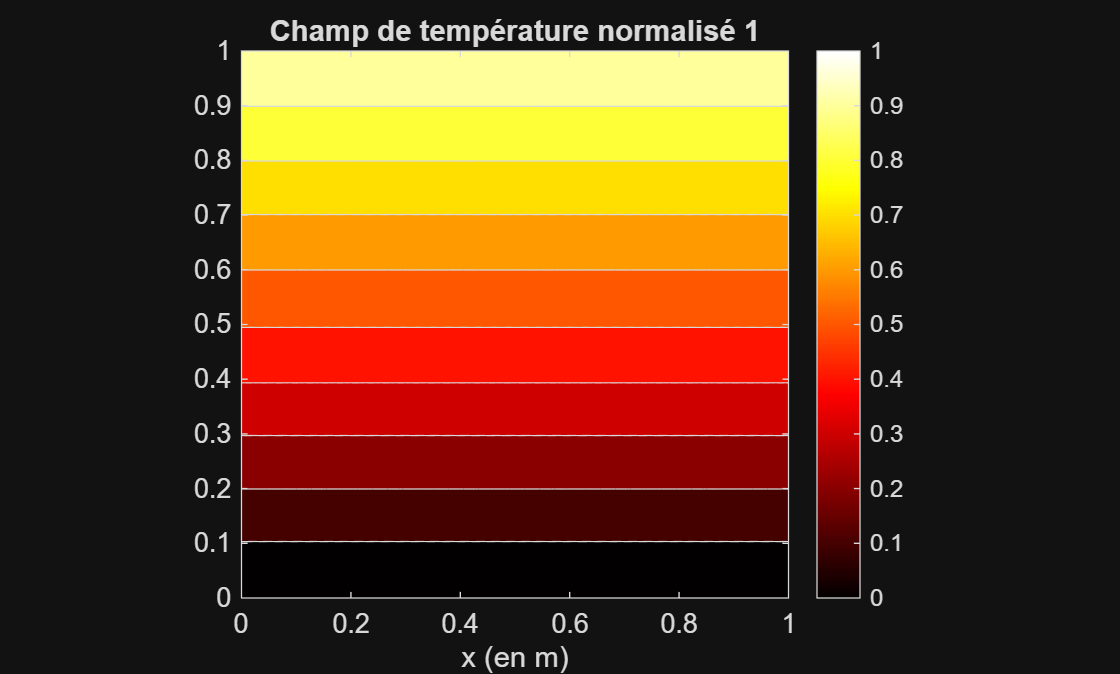


% Tracé cas charges en lignes (cas le moins conducteur)

Tet=reshape(X,Ny,Nx);
Tet = flipud(Tet); 
k = flipud(k); 
contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
title('Champ de température normalisé 1')
xlabel('x (en m)')
colorbar();
axis equal

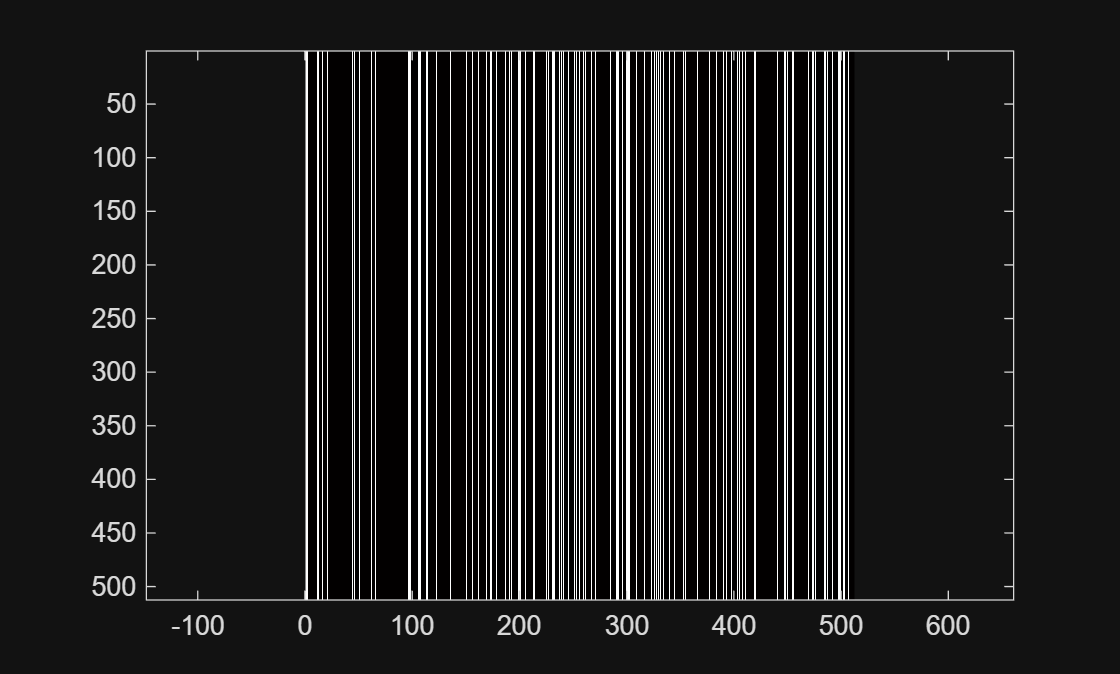


% Génération des charges en colonnes (cas le plus conducteur)

[kmax, tempFs, filename] = PercolationGenerator2Dmax(Nx, Ny, Lx, Ly, r, fs, false, false);
[X, k, dx, dy] = resVolFini2D(Nx, Ny, kmin, kc, ki, Lx, Ly);

figure;
imagesc(kmax);
colormap(hot);
axis equal


% Tracé cas charges en colonnes (cas le plus conducteur)

Tet=reshape(X,Ny,Nx);
Tet = flipud(Tet); 
k = flipud(k); 
contourf(0:dx:Lx, 0:dy:Ly, Tet)                     % Trace les isothermes 
title('Champ de température normalisé 1')
xlabel('x (en m)')
colorbar();
axis equal


% Calcul du flux
% On calcule le flux sur chaque ligne

Phi = sum((1./(1./k(1:Ny-1,:) + 1./k(2:Ny,:))).*(Tet(2:Ny,:)-Tet(1:Ny-1,:))*(2*dx/dy),2);

% Vérification de la conservation du flux

Phi_moy = mean(Phi); % Flux moyen

Diff = max(Phi(:) - Phi_moy)/Phi_moy

Diff = 1.9055e-11


if Diff > 10^(-6)
    fprintf('Non-conservation du flux')
else 
    fprintf('Conservation du flux')
end

Conservation du flux